% Exponential Growth
% UCI COSMOS 2022:  Tissue and Tumor Modeling (Cluster 3)

clear

## User-defined inputs

TimeStep = 1;        % Time step (baseline = 0.01)
InitialPopulation = 200;  % Initial condition (baseline = 3)
lambdam = 1;          % Growth rate (baseline = 0.5)
endTime = 10;           % End time of simulation (baseline = 10)
theta = 100;
alpha = 2;

## Begin simulation

% Program execution parameters
dT = TimeStep;
tsteps = ceil(endTime/dT) + 1;    % Number of time steps required

% Pre-allocate vectors for faster runtime
Time = zeros(1,tsteps);
N = zeros(1,tsteps);

% Set initial time and initial population
Time(1) = 0;                % Set initial time to zero
N(1) = InitialPopulation;   % Set initial population

% Euler Method
for n = 2:tsteps
    Time(n) = (n-1)*dT;                 % Compute the current time
    N(n) = N(n-1) + dT*(lambdam*N(n-1)*(1-(N(n-1)/theta)^2));  % Compute the population size
end
% lambda = 1;
% theta = 1000;
% alpha = 2;
% dNdt = lambda*N*(1-(N/theta)^alpha);

raw = readtable("Raw data_MCSBBootcampBacterialPopulationGrowth.txt");

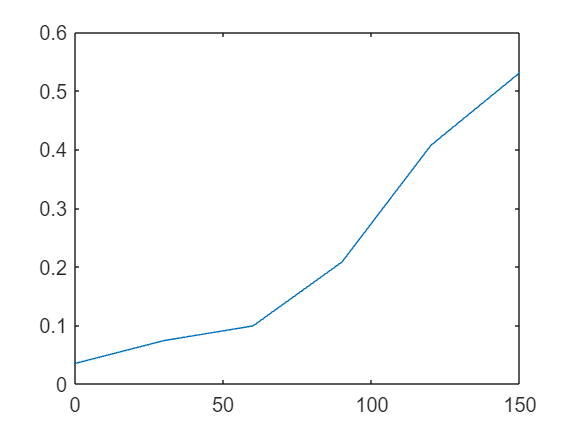

data = table2array(raw);

noglu = data(:,2);
time = data(:,1);
plot(time,noglu);

## Plotting

ExactPopulation = InitialPopulation*exp(lambdam*Time);

ExactPopulation =     3.0000    3.0150    3.0302    3.0453    3.0606    3.0759    3.0914    3.1069    3.1224    3.1381    3.1538    3.1696    3.1855    3.2015    3.2175    3.2337    3.2499    3.2662    3.2825    3.2990    3.3155    3.3321    3.3488    3.3656    3.3825    3.3994    3.4165    3.4336    3.4508    3.4681    3.4855    3.5030    3.5205    3.5382    3.5559    3.5737    3.5917    3.6097    3.6277    3.6459    3.6642    3.6826    3.7010    3.7196    3.7382    3.7570    3.7758    3.7947    3.8137    3.8329


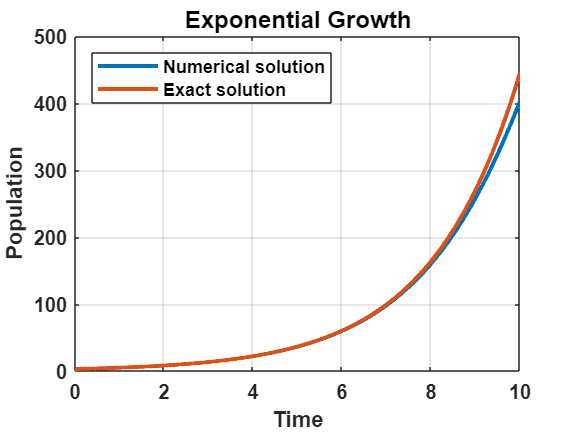


figure,plot(Time,N,Time,ExactPopulation,'LineWidth',2)
xlabel('Time','FontWeight','bold')
ylabel('Population','FontWeight','bold')
grid on
legend('Numerical solution','Exact solution','Location','NorthWest')
title('Exponential Growth','FontSize',12,'FontWeight','bold')
set(gca,'FontWeight','bold')